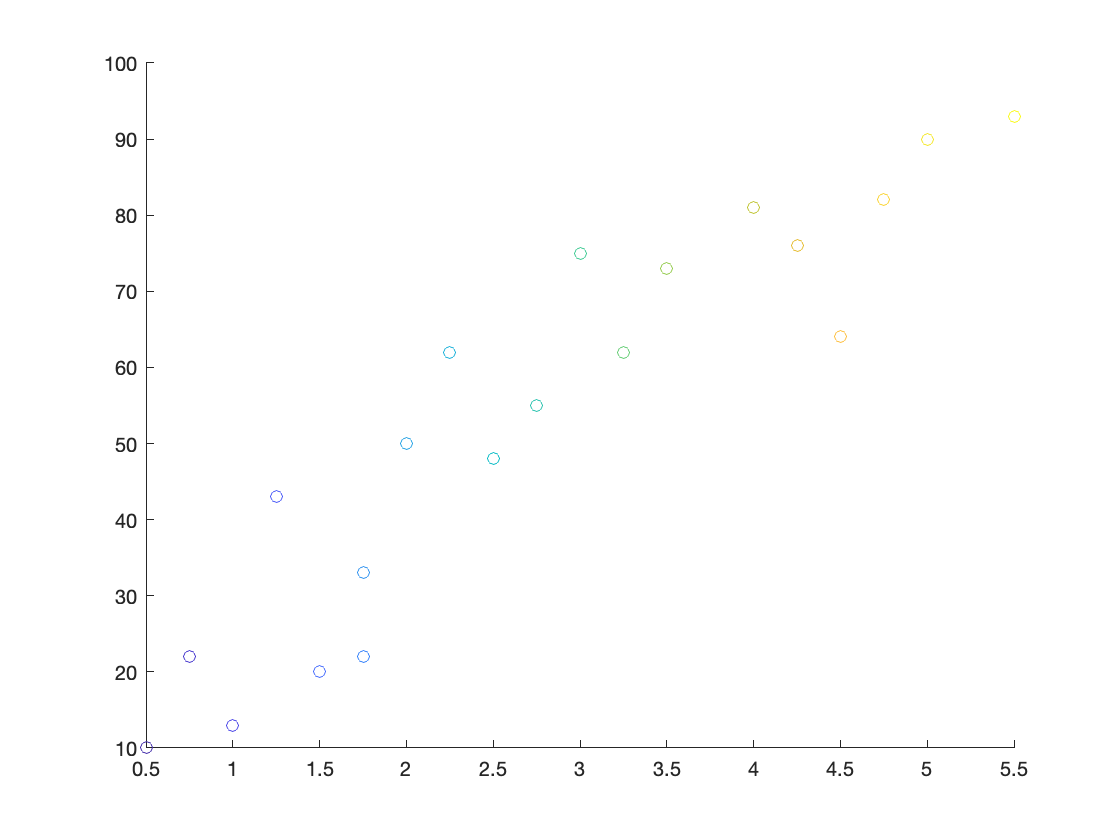

% Create a scatter plot and vary the circle color.
x = [0.50,0.75,1.00,1.25,1.50,1.75,1.75,2.00,2.25, 2.50,2.75,3.00,3.25,3.50,4.00,4.25,4.50,4.75,5.00,5.50];
y = [10, 22, 13, 43, 20, 22, 33, 50, 62, 48, 55, 75, 62, 73, 81, 76, 64, 82, 90, 93];
c = linspace(1,10,length(x));
scatter(x,y,[],c)

R = corrcoef(x,y)

R =     1.0000    0.9240
    0.9240    1.0000


% Correlation coefficient is 0.9240

% Fit a polynomial of degree 8 to the 20 points. 
% In general, for n points, you can fit a polynomial of degree n-1 to exactly pass through the points.
p = polyfit(x,y,8);

% Evaluate the original function and the polynomial fit
f1 = polyval(p,x);

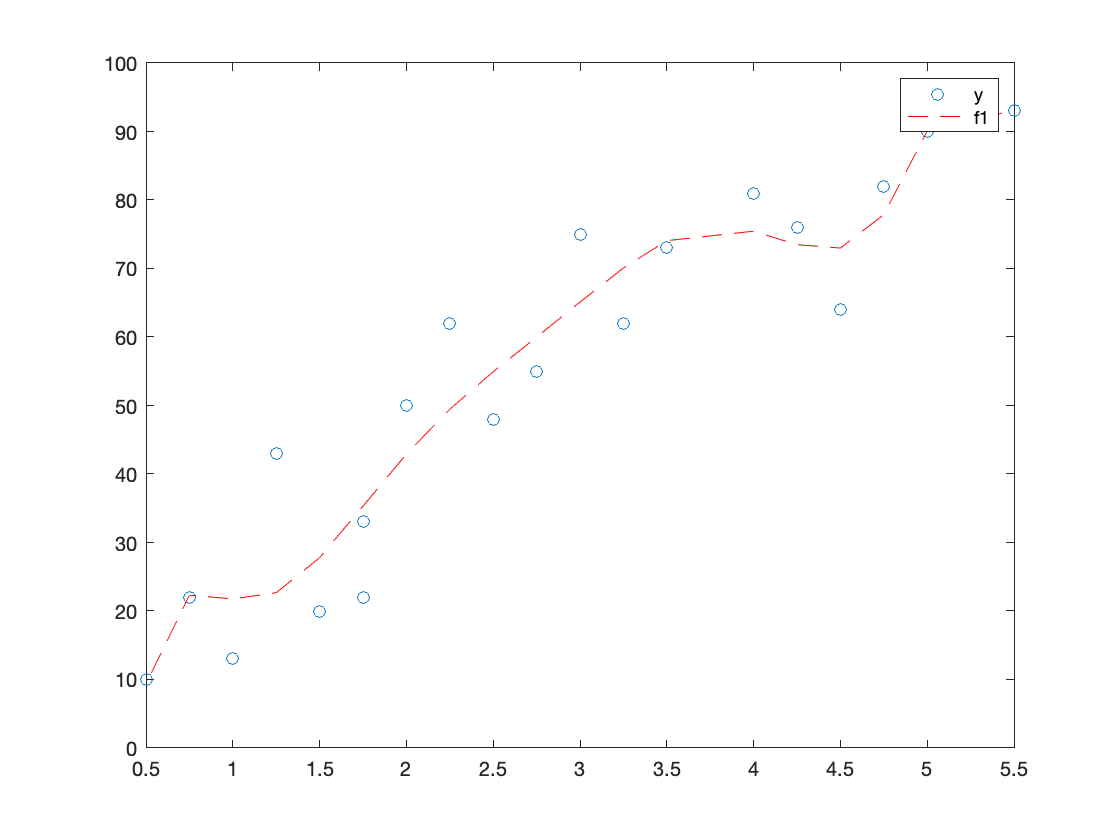

% Plot the function values and the polynomial fit in the interval [0.5,5.5], with the points used to obtain the polynomial fit highlighted as circles.
figure
plot(x,y,'o')
hold on
plot(x,f1,'r--')
legend('y','f1')